# Hands-On: Polynomial Regression

## Introduction

Having collected $N$ data for the variables $y(t)$ and $u(t)$, over the time window $t = 1,\,2,\, \ldots N$, we want to compute (if possible) $q+1$ parameters $\vartheta_0,\,\vartheta_1,\,\vartheta_2,\, \ldots \vartheta_q$ such that


$$y(t) = \vartheta_q\, u^q(t) + \vartheta_{q-1}\,u^{q-1}(t) + \cdots \, + \vartheta_1\,u(t) + \vartheta_0\quad , \qquad t=1,\,2,\,\ldots\,N \qquad (+)$$


The stated problem is a polynomial regression problem, given the degree $q$ of the polynomial. Rewriting in a compact form the Eq. (+), the regression problem appears as **a linear in the parameters problem**, so we can solve it by applying the LS approach


$$y(t) = \left[ \begin{array}{ccccc}
1 & u(t) & u^2(t) & \cdots & u^{q}(t)
\end{array} \right]^{\top} \cdot \left[ \begin{array}{c}
\vartheta_0 \\ \vartheta_1 \\ \vdots \\ \vartheta_{q-1} \\ \vartheta_q
\end{array} \right] \qquad t=1,\,2,\, \cdots\,N$$


### Important Remark

Obviously, we know **perfectly a-priori** what is the degree $q$ of the polynomial regression function to determine.

clear
close all
clc


## Solving the Polynomial Regression Problem 

Let's start selecting the degree $q$ of the polynomial function to estimate

Nq = 10; % the degree q of the polynomial curve to be estimated

Generate a random polynomial. We will use it to generate the data

coeff_v = -10 + 20 * rand(Nq,1); % the "true" polynomial coefficients

Tune the variance of the additive noise acting on the data, collected during the simulated experiment

sigma2_n = 10; % the variance of the additive noise

### Collecting the Data

How many data?

Ndata = 700; % the data we will collect during the simulated experiment

Setting the constraints on the variable $u$

Umin = -2; Umax = 3; % the extrema for the variable u
U_i = Umin + (Umax-Umin)*rand(Ndata,1); % the data used for the independent variable/regressor

Now let's simulate the collection of the data from the simulated systtem

add_noise = sqrt(sigma2_n) * randn(Ndata,1); % the noise samples

Y_i = polyval(coeff_v, U_i) + add_noise; % the data we collected 

Plotting the raw data

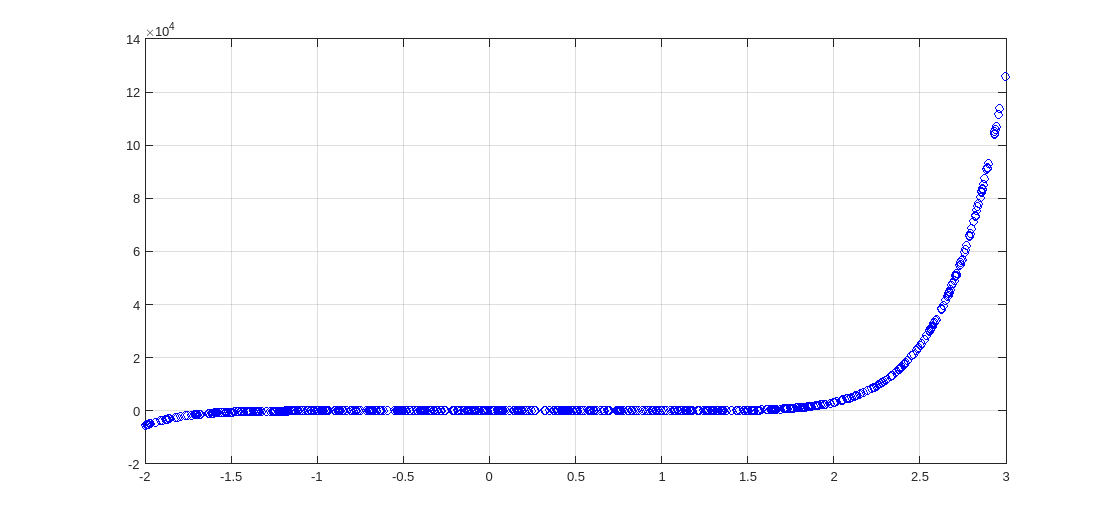

figure('Units', 'normalized', 'Position',[0.1, 0.1, 0.9, 0.75]);
plot(U_i, Y_i,'bo'); grid on;

### Looking for a Model

Building the regressor matrix $\Phi_N$ and the observation vector $Y_N$


$$\Phi_{N}\cdot \vartheta = Y_{N}$$


regressorMAT = ones(length(U_i),1); % initialization of the regressor matrix

Y_N = reshape(Y_i, length(Y_i),1); % the vector Y_N (as column vector)

[Us, idx]= sort(U_i);

%degree = Nq; % <-- NB we know it!!
for degree=1:Nq
    regressorMAT = [reshape(U_i, length(U_i),1) .^degree ,regressorMAT];
end
% the matrix Phi_N    


Solving the equation


$$\hat{\vartheta}_{N} = \left( \Phi_N^{\top}\,\Phi_N\right)^{-1}\,\Phi_N\,Y_N $$


    hat_thetaN = regressorMAT \ Y_N;

### Comparing the Data with the Model

model = polyval(hat_thetaN,U_i); % using the model
errors = Y_i - model; 

% plotting the results - comparing with the raw data and plotting the
% regression errors
figure('Units', 'normalized', 'Position',[0.1, 0.1, 0.9, 0.75]);

subplot(2,1,1)
plot(U_i, Y_i, 'bo'); % the raw data

hold on;
plot(Us, model(idx), 'x-r'); % the model output
grid on; hold off;

subplot(2,1,2);
plot(Us, errors(idx), '-b');

Some statistics about the error:

mean(errors)

var(errors)